dist_to_detector = 2

dist_to_detector = 2

% my_voxels = voxel_cross([1000;1000;1000], 200);
my_voxels = voxel_shepp_logan(2000);
pixel_width = 2e-3

pixel_width = 0.0020

my_array = voxel_array(zeros(3, 1), [0.4; 0.4; 0.4], 2e-4, my_voxels)

my_array =   voxel_array with properties:

    array_position: [3×1 double]
        num_planes: [3×1 double]
        dimensions: [3×1 double]
      get_voxel_mu: @voxel_shepp_logan/voxel_cross


detector_width = 1;
num_xrays_per_angle = 2501;
total_rotation = deg2rad(179)

total_rotation = 3.1241

num_scan_angles = 180

num_scan_angles = 180

source_position = [0; 1; 0];

zrot90 = zrot(pi/2)

zrot90 =     0.0000   -1.0000         0
    1.0000    0.0000         0
         0         0    1.0000


source_rot_mat = zrot(total_rotation/(num_scan_angles-1))

source_rot_mat =     0.9998   -0.0175         0
    0.0175    0.9998         0
         0         0    1.0000


to_ray_start_mat = @(vec) (zrot90 * vec) .* detector_width/2

to_ray_start_mat = function_handle with value:
    @(vec)(zrot90*vec).*detector_width/2


ray_trans_mat    = @(vec) - (zrot90 * vec) .* (detector_width ./ (num_xrays_per_angle-1))

ray_trans_mat = function_handle with value:
    @(vec)-(zrot90*vec).*(detector_width./(num_xrays_per_angle-1))



num_detectors = ceil(detector_width / pixel_width)

num_detectors = 500

my_detector = parallel_detector(source_position, source_position.*-1, dist_to_detector, detector_width, pixel_width)

my_detector =   parallel_detector with properties:

        pixel_width: 0.0020
     detector_width: 1
    detector_centre: [3×1 double]
         num_pixels: 500


my_ray = ray(zeros(3, 1), zeros(3, 1), dist_to_detector); %Slow!
image = zeros(num_detectors, num_scan_angles);
tic
% profile on
for angle = 1:num_scan_angles
    % Get the unit vector from source to detector
    % source_position
    % vec_to_detector
    vec_to_detector = source_position.*-1;
    vec_to_detector = vec_to_detector ./ sum(vec_to_detector .^ 2);% pointless for now
    
    % Move the initial direction and position of the rays
    ray_position = to_ray_start_mat(vec_to_detector) + source_position;
    ray_translation = ray_trans_mat(vec_to_detector);
    my_ray = my_ray.update_parameters(ray_position, vec_to_detector);
    
    %Initalise arrays
    mu_array = zeros(1, my_detector.num_pixels);
    num_hits = zeros(1, my_detector.num_pixels);

    %Start looping through rays translating them
    for iray = 1:num_xrays_per_angle
        %ray_position

        % Collate tracing results
        hit_pixel = my_detector.get_hit_pixel(my_ray);
        mu = my_ray.calculate_mu(my_array);
        mu_array(hit_pixel) = mu_array(hit_pixel) + mu;
        num_hits(hit_pixel) = num_hits(hit_pixel) + my_ray.energy;
        
        %Move ray around
        ray_position = ray_position + ray_translation;
        my_ray = my_ray.move_start_point(ray_position);  
    end
    % Calculate image number
    image(:, angle) = num_hits .* exp(-mu_array);

    %Rotate the source around
    source_position = source_rot_mat * source_position;
    my_detector = my_detector.rotate_detector(total_rotation/(num_scan_angles-1));
end
toc

Elapsed time is 69.334149 seconds.


% profile viewer
image

image =      6     6     5     6     5     6     6     6     5     5     6     5     5     5     5     5     6     5     5     6     6     6     6     6     5     5     6     6     6     6     6     6     6     5     5     6     6     5     5     5     5     6     6     5     5     5     5     5     6     6
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     

image

image =      6     6     5     6     5     6     6     6     5     5     6     5     5     5     5     5     6     5     5     6     6     6     6     6     5     5     6     6     6     6     6     6     6     5     5     6     6     5     5     5     5     6     6     5     5     5     5     5     6     6
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5     5
     5     5     5     5     5     5     5     5     5     5     5     5     5     5     

I = mat2gray(-log(image))

I =          0         0    0.1478         0    0.1478         0         0         0    0.1478    0.1478         0    0.1478    0.1478    0.1478    0.1478    0.1478         0    0.1478    0.1478         0         0         0         0         0    0.1478    0.1478         0         0         0         0         0         0         0    0.1478    0.1478         0         0    0.1478    0.1478    0.1478    0.1478         0         0    0.1478    0.1478    0.1478    0.1478    0.1478         0         0
    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0.1478    0

scan_angles = rad2deg(linspace(0, total_rotation, num_scan_angles))

scan_angles =          0    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   11.0000   12.0000   13.0000   14.0000   15.0000   16.0000   17.0000   18.0000   19.0000   20.0000   21.0000   22.0000   23.0000   24.0000   25.0000   26.0000   27.0000   28.0000   29.0000   30.0000   31.0000   32.0000   33.0000   34.0000   35.0000   36.0000   37.0000   38.0000   39.0000   40.0000   41.0000   42.0000   43.0000   44.0000   45.0000   46.0000   47.0000   48.0000   49.0000


%{
for i = 1:num_scan_angles
    plot(I(:,i))
    drawnow
end
%}
[R, H] = iradon(I, scan_angles)%, "linear", "None")

R =     0.0009    0.0014    0.0017   -0.0008    0.0004    0.0003    0.0011    0.0018    0.0026    0.0023    0.0008    0.0001   -0.0004   -0.0003   -0.0003   -0.0003    0.0011    0.0014    0.0012    0.0007    0.0007    0.0006   -0.0005   -0.0001    0.0010    0.0008    0.0005    0.0012    0.0008    0.0005   -0.0003   -0.0001    0.0006    0.0010    0.0006    0.0005    0.0009    0.0002   -0.0002    0.0002    0.0003    0.0010    0.0013    0.0009    0.0004   -0.0003    0.0003    0.0006    0.0009   -0.0003
    0.0010    0.0033    0.0035    0.0015    0.0012    0.0008    0.0005   -0.0001   -0.0006    0.0000    0.0012    0.0011    0.0008    0.0011    0.0009   -0.0001    0.0001    0.0002    0.0014    0.0003    0.0010    0.0012    0.0005    0.0001    0.0001    0.0000    0.0003    0.0009    0.0013    0.0011    0.0005   -0.0000    0.0003   -0.0001    0.0000    0.0013    0.0012    0.0008    0.0004    0.0004   -0.0000    0.0002    0.0008    0.0014    0.0002   -0.0006   -0.0005   -0.0001   -0.0009    0

H =     0.0004
    0.0019
    0.0039
    0.0059
    0.0078
    0.0098
    0.0117
    0.0137
    0.0156
    0.0176


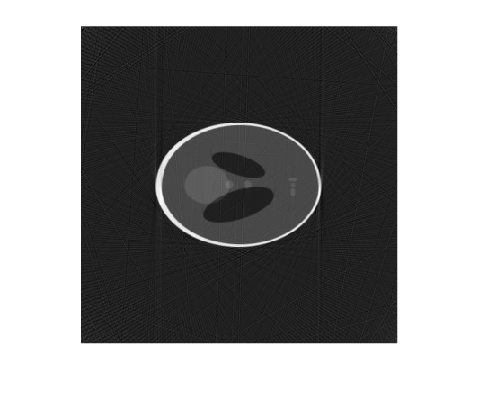

imwrite(R, 'filtered back.png')
imwrite(I, 'sinogram.png')

%plot(H)
imshow(R, [])

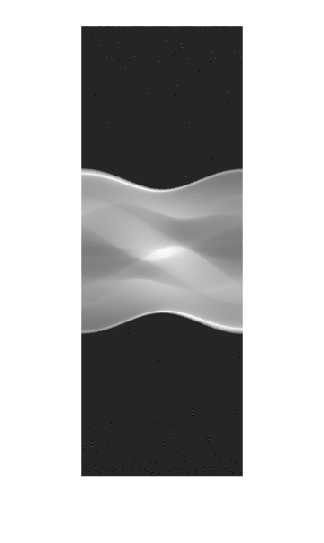

imshow(I, [])